% Author: Yuzuke Azuma
% Copyright 2019 RIKEN BDR
% License: GPL v3 https://www.gnu.org/licenses/gpl-3.0.txt 

%{
Requirements: Image Processing Toolbox, Statistics and Machine Learning Toolbox

Sections starting with "% %" are only for test, not needed for the image
processing. e.g. showing images

%}

% Load image data
imgFilename = 'nuclearImage.mat';
file = load(imgFilename);% Loads variables in the MAT-File (~.mat) into the workspace
img = file.img;%'img' is the name of variable
img = single(img);

% % Show size of the img
size(img)

ans =    147   125    52    34


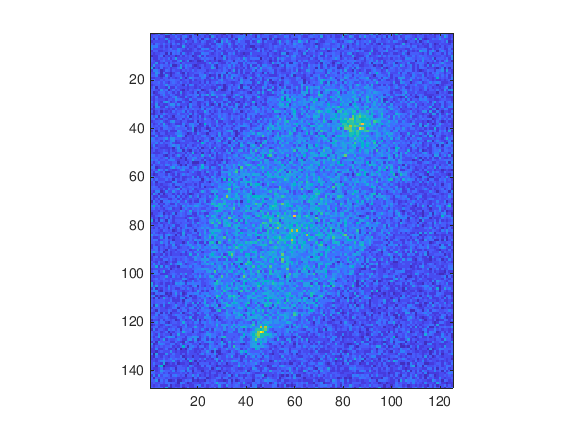

% % Show a slice
imagesc(img(:,:,12,1))
daspect([1,1,1])

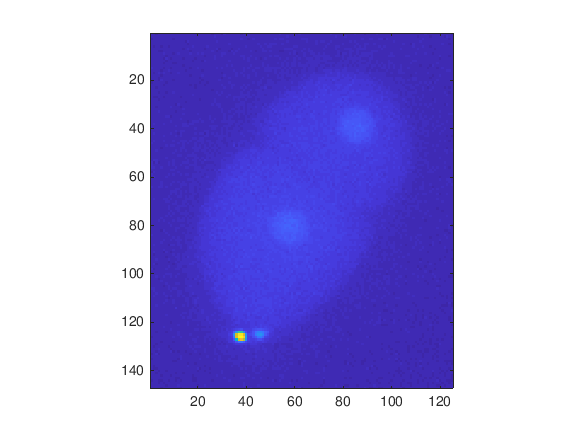

% % Show Z projection
imagesc(sum(img(:,:,:,1), 3))
daspect([1,1,1])

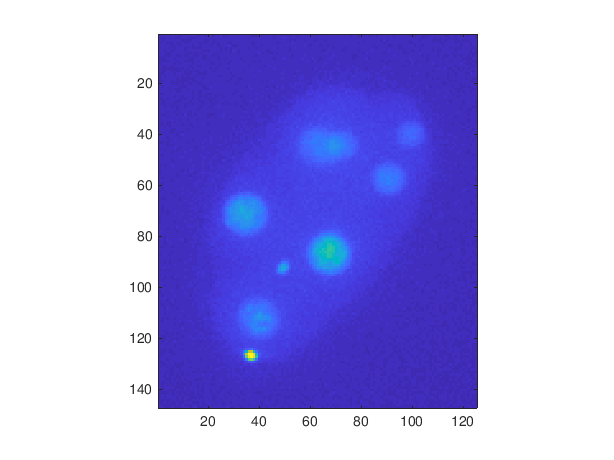

% % Repeat showing Z projection time by time
figure
set(gcf,'Visible','on')
for i = 1:size(img, 4)
    imagesc(sum(img(:,:,:,i), 3))
    daspect([1,1,1])
    drawnow
    pause(0.3)% Pause ~ second
end

%% ---------------------- Segmentation ----------------------

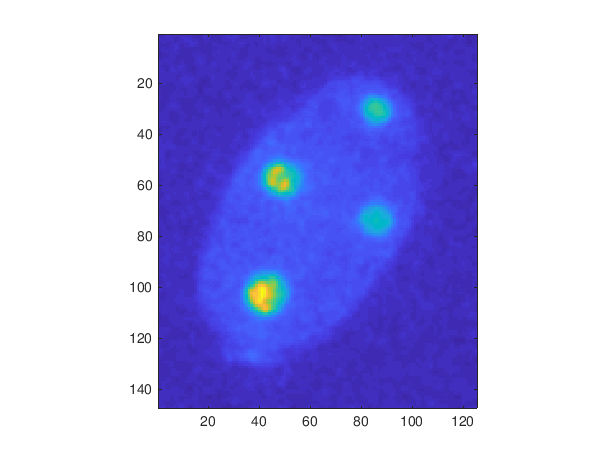

% % Denoising by Gaussian filter 1
sigma = 1;
denoise = imgaussfilt3(img(:,:,:,18), sigma);
imagesc(denoise(:,:,18));
daspect([1,1,1])

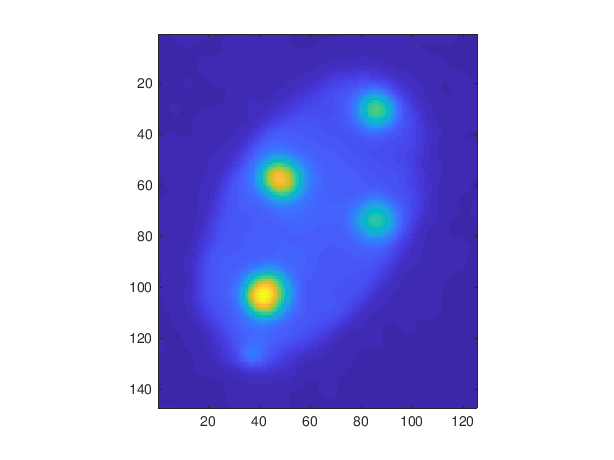

% % Denoising by Gaussian filter 2
sigma = 3;
denoise = imgaussfilt3(img(:,:,:,18), sigma);
imagesc(denoise(:,:,18));
daspect([1,1,1])

% Denoising by 3D Difference of Gaussian filter
% Edge is well detected
filtersize = 13;
sigma1 = 4;
sigma2 = 6;
denoise = zeros(size(img));
for i = 1:size(img,4)
    thisImg = img(:,:,:,i);
    stack1 = imgaussfilt3(thisImg, sigma1,'FilterSize', filtersize);
    stack2 = imgaussfilt3(thisImg, sigma2,'FilterSize', filtersize);
    denoise(:,:,:,i) = stack1 - stack2;
end

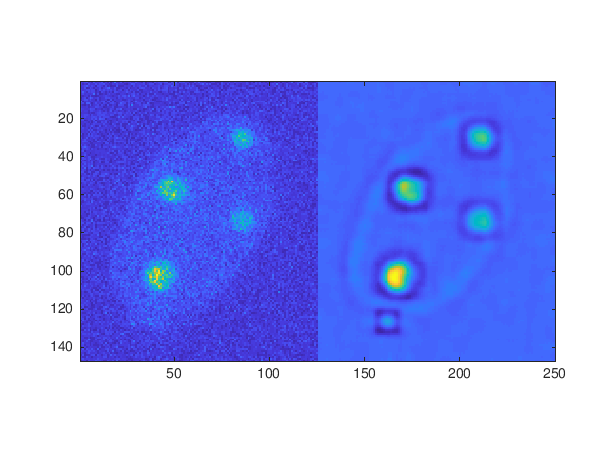

% % Show a slice
combinedImg = [mat2gray(img(:,:,18,18)), mat2gray(denoise(:,:,18,18))];% mat2gray converts image into that with intensity 0-1
imagesc(combinedImg)
daspect([1,1,1])

denoise(:,:,1,10)

ans =     0.0195    0.0046   -0.0037   -0.0193   -0.0162   -0.0209   -0.0259   -0.0203   -0.0148   -0.0319   -0.0149    0.0038    0.0195    0.0049    0.0285    0.0289    0.0209    0.0034   -0.0122   -0.0136   -0.0336   -0.0026    0.0408    0.0558    0.0384    0.0065    0.0085   -0.0036   -0.0197   -0.0021    0.0050    0.0354    0.0351    0.0289   -0.0131   -0.0557   -0.0701   -0.0632   -0.0294   -0.0109    0.0108    0.0610    0.0569    0.0470    0.0043   -0.0285   -0.0374   -0.0348   -0.0193   -0.0258
    0.0010   -0.0102   -0.0160   -0.0259   -0.0215   -0.0200   -0.0218   -0.0144   -0.0136   -0.0339   -0.0259   -0.0129   -0.0015   -0.0148    0.0043    0.0056    0.0041   -0.0042   -0.0138   -0.0113   -0.0276    0.0055    0.0410    0.0552    0.0382    0.0083    0.0087   -0.0006   -0.0158   -0.0036    0.0017    0.0263    0.0280    0.0242   -0.0129   -0.0447   -0.0547   -0.0510   -0.0210   -0.0080    0.0096    0.0504    0.0446    0.0329    0.0006   -0.0270   -0.0328   -0.0316   -0.0163   

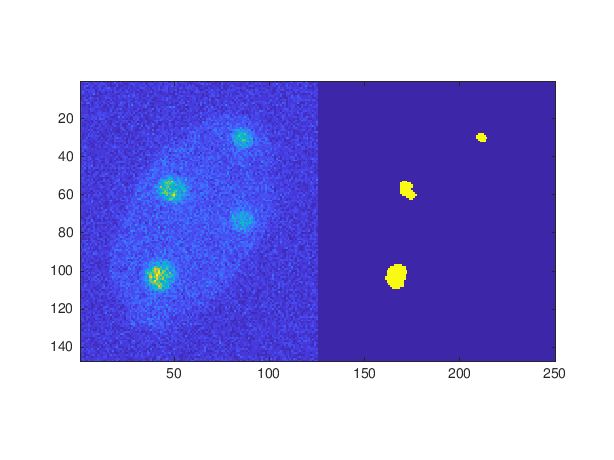

% % Thresholding
bw = denoise > 0.6;

% putting the image side by side with the same image thresholding at 0.6
combinedImg = [mat2gray(img(:,:,18,18)), mat2gray(bw(:,:,18,18))];
imagesc(combinedImg)
daspect([1,1,1])

% Thresholding by mean and std
meanInt = mean(denoise(:));% Mean of pixels of whole 4D image by ':'
stdInt = std(double(denoise(:)));
bw = denoise > meanInt + 2*stdInt;

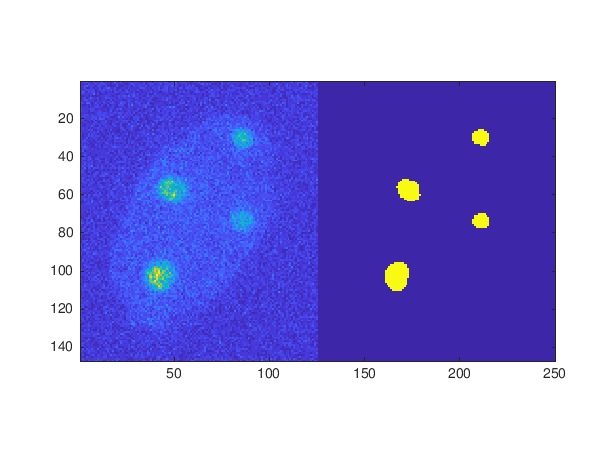

% % Show a slice
combinedImg = [mat2gray(img(:,:,18,18)), mat2gray(bw(:,:,18,18))];
imagesc(combinedImg)
daspect([1,1,1])

% Assign unique ID (pixel intensity)
lab = bwlabeln(bw, 26); % 26 means connectivity for 3D objects

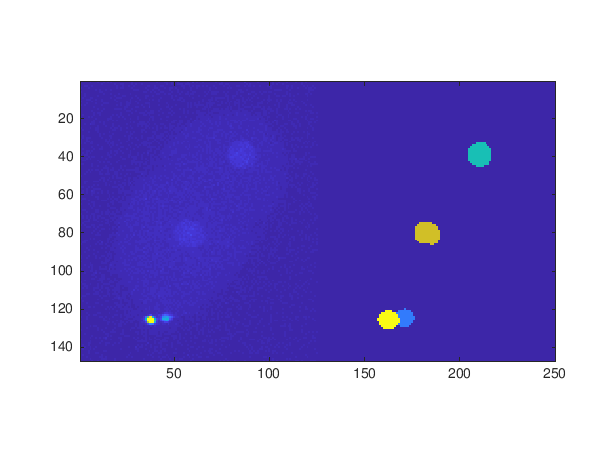

% % Show Z projection 
combinedImg = [mat2gray(max(img(:,:,:,1), [], 3)), mat2gray(max(lab(:,:,:,1), [], 3))];
imagesc(combinedImg)% Each region is assigned different intensity (color)
daspect([1,1,1])

% % Repeat showing Z projection time by time
figure
set(gcf,'Visible','on')
for t = 1:size(img, 4)
% sum all the pixel value of the slices at time t and display the Z value
    imagesc(sum(img(:,:,:,t), 3))
    daspect([1,1,1])
    pause(0.3)% Pause ~ second
end

% There are two polar bodies, one of which does not move and the 
% other moves. They can be detected as regions with high intensities.

% Remove polar bodies
nuc = lab;
int = regionprops(nuc, img, 'MaxIntensity');
int = cat(1, int.MaxIntensity);
polarIDs = find(int > 102);
nuc(ismember(nuc, polarIDs)) = 0;

% Re-label
nuc = bwlabeln(nuc, 26);


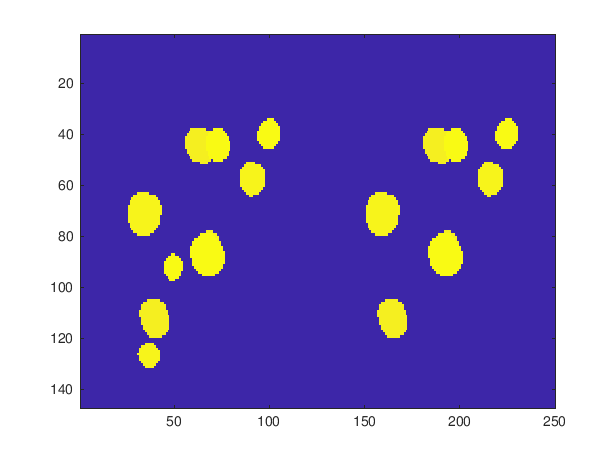

% % Repeat showing Z projection time by time
figure
set(gcf,'Visible','on')
for i = 1:size(lab, 4)
    combinedImg = [mat2gray(max(lab(:,:,:,i), [], 3)), mat2gray(max(nuc(:,:,:,i), [], 3))];
    imagesc(combinedImg)
    pause(0.3)% Pause ~ second
end

%% ---------------------- Tracking ----------------------

% Coordinates of nuclei
data = regionprops(nuc, 'Centroid') % data = x,y,z,t

data = 158×1 struct array with fields:
    Centroid


data = cat(1, data.Centroid)

data =    85.5614   38.8843   19.5743    1.0000
   57.8292   80.2807   23.0650    1.0000
   88.6689   37.6518   19.8410    2.0000
   58.5529   80.5278   19.1942    2.0000
   53.2856   80.8286   22.5194    3.0000
   88.2111   39.9851   22.1920    3.0000
   84.1556   37.7202   24.5444    4.0000
   52.3521   82.5772   26.0998    4.0000
   80.9449   41.5713   25.0800    5.0000
   53.9051   83.1319   25.1889    5.0000


% % Show data
% disp(data);


% Add ids into data
id = 1:size(data, 1); % Creating an index

data = [data, id'] % ' function rotates the id array 90 degrees; data = x,y,z,t,id

data =    85.5614   38.8843   19.5743    1.0000    1.0000
   57.8292   80.2807   23.0650    1.0000    2.0000
   88.6689   37.6518   19.8410    2.0000    3.0000
   58.5529   80.5278   19.1942    2.0000    4.0000
   53.2856   80.8286   22.5194    3.0000    5.0000
   88.2111   39.9851   22.1920    3.0000    6.0000
   84.1556   37.7202   24.5444    4.0000    7.0000
   52.3521   82.5772   26.0998    4.0000    8.0000
   80.9449   41.5713   25.0800    5.0000    9.0000
   53.9051   83.1319   25.1889    5.0000   10.0000


% Confirm the data by: right click -> open "data"

% % Show data
disp(data);

   85.5614   38.8843   19.5743    1.0000    1.0000
   57.8292   80.2807   23.0650    1.0000    2.0000
   88.6689   37.6518   19.8410    2.0000    3.0000
   58.5529   80.5278   19.1942    2.0000    4.0000
   53.2856   80.8286   22.5194    3.0000    5.0000
   88.2111   39.9851   22.1920    3.0000    6.0000
   84.1556   37.7202   24.5444    4.0000    7.0000
   52.3521   82.5772   26.0998    4.0000    8.0000
   80.9449   41.5713   25.0800    5.0000    9.0000
   53.9051   83.1319   25.1889    5.0000   10.0000
   79.5087   41.9891   26.4871    6.0000   11.0000
   53.1037   83.4850   26.4567    6.0000   12.0000
   81.1570   43.7800   25.3279    7.0000   13.0000
   55.2252   84.7850   25.5224    7.0000   14.0000
   52.3305   84.9431   25.7610    8.0000   15.0000
   80.7100   43.9312   26.2232    8.0000   16.0000
   85.8391   48.7546   26.2065    9.0000   17.0000
   48.2000   74.7612   27.3582    9.0000   18.0000
   51.6170   91.0334   27.3328    9.0000   19.0000
   82.0910   44.5644   26.6769 

% Nearest neighbor association
time = data(:,4);
finaltime = max(time)

finaltime = 34

for i = 1:10
    prePositions = data(time == i, 1:3);% x,y,z of time = i
    postPositions = data(time == i+1, 1:3);% x,y,z of time = i+1
    
    % Nearest nucleus at pre is identified for each nucleus at post
    % 
    % [D,I] = pdist2(X,Y,'euclidean','Smallest',1)
    % For each observation in Y, pdist2 finds the smallest distances by computing and 
    % comparing the distance values to all the observations in X. 
    % The function then sorts the distances in each column of D in ascending order. 
    % I contains the indices of the observations in X corresponding to the distances in D.
    [distance, index] = pdist2(prePositions, postPositions, 'euclidean', 'Smallest', 1);
    disp(distance);
    disp(index);
end

    3.3536    3.9456



     1     2



    6.2364    3.3438



     2     1



    5.2069    4.0924



     2     1



    5.0425    1.8839



     1     2



    2.0536    1.5408



     1     2



    2.6960    2.6578



     1     2



    2.9089    1.0121



     2     1



    7.0408   11.1032    6.3303



     2     1     1



    5.6416    3.3996    3.5039



     1     2     3



    4.9496    7.0739    7.9516   11.4085



     3     2     1     1



% Nearest neighbor association
% The following is to see how the algorithm works. It tries to only
% calculate 10 time points and display the dividedID.
time = data(:,4);
finaltime = max(time)

finaltime = 34

for i = 1:10
    prePositions = data(time == i, 1:3);% x,y,z of time = i
    postPositions = data(time == i+1, 1:3);% x,y,z of time = i+1
    
    % Nearest nucleus at pre is identified for each nucleus at post
    % 
    [distance, index] = pdist2(prePositions, postPositions, 'euclidean', 'Smallest', 1);
    % Nearest ID at prePositions
    preIDs = data(time == i, 5);
    nearestPreIDs = preIDs(index);

    % Replace ID at postPositions with ID of nearest at prePositions
    data(time == i+1, 5) = nearestPreIDs;
    
    % Find cell divisions
    postIDs = data(time == i+1, 5);
    % fprintf('postIDs %3d\n', postIDs);
    num = arrayfun(@(x) nnz(x==postIDs), postIDs);
    dividedIDs = postIDs(num==2);
    fprintf('time: %d \n', i);
    if isempty(dividedIDs)
        disp('dividedID = None')
    else
        disp(["dividedIDs =" dividedIDs']);
    end
end

time: 1 


dividedID = None


time: 2 


dividedID = None


time: 3 


dividedID = None


time: 4 


dividedID = None


time: 5 


dividedID = None


time: 6 


dividedID = None


time: 7 


dividedID = None


time: 8 


    "dividedIDs ="    "2"    "2"



time: 9 


    "dividedIDs ="    "2"    "2"



time: 10 


    "dividedIDs ="    "2"    "2"    "1"    "1"



% Nearest neighbor association
time = data(:,4);
finaltime = max(time)

finaltime = 34

for i = 1:finaltime-1    
    prePositions = data(time == i, 1:3);% x,y,z of time = i
    postPositions = data(time == i+1, 1:3);% x,y,z of time = i+1
    
    % Nearest nucleus at pre is identified for each nucleus at post
    [distance, index] = pdist2(prePositions, postPositions, 'euclidean', 'Smallest', 1);
    
    % Nearest ID at pre
    preIDs = data(time == i, 5);
    nearestPreIDs = preIDs(index);

    % Replace ID at post with ID of nearest at pre
    data(time == i+1, 5) = nearestPreIDs;
    
    % Find cell divisions
    postIDs = data(time == i+1, 5);
    num = arrayfun(@(x) nnz(x==postIDs), postIDs); % nnz - number of nonzero matrix elements
    dividedIDs = postIDs(num==2); % in this example, we only have 2 nearest neighbours.
    
    % Change IDs of divided nuclei 
    if ~isempty(dividedIDs) % if dividedIDs is not empty, i.e. division occurs.
        lines = data(:, 4) == i+1 & ismember(data(:, 5), dividedIDs);% If data is at time i+1 and belongs to dividedIDs, then return Lines
        data(lines, 5) = max(data(:, 5)) + 1 : max(data(:, 5)) + length(dividedIDs);% New IDs are assigned to the (max size of data + 1) or (max size of data + size of cell division (dividedIDs))
    end
    
end

% % Show data
disp(data);

   85.5614   38.8843   19.5743    1.0000    1.0000
   57.8292   80.2807   23.0650    1.0000    2.0000
   88.6689   37.6518   19.8410    2.0000    1.0000
   58.5529   80.5278   19.1942    2.0000    2.0000
   53.2856   80.8286   22.5194    3.0000    2.0000
   88.2111   39.9851   22.1920    3.0000    1.0000
   84.1556   37.7202   24.5444    4.0000    1.0000
   52.3521   82.5772   26.0998    4.0000    2.0000
   80.9449   41.5713   25.0800    5.0000    1.0000
   53.9051   83.1319   25.1889    5.0000    2.0000
   79.5087   41.9891   26.4871    6.0000    1.0000
   53.1037   83.4850   26.4567    6.0000    2.0000
   81.1570   43.7800   25.3279    7.0000    1.0000
   55.2252   84.7850   25.5224    7.0000    2.0000
   52.3305   84.9431   25.7610    8.0000    2.0000
   80.7100   43.9312   26.2232    8.0000    1.0000
   85.8391   48.7546   26.2065    9.0000    1.0000
   48.2000   74.7612   27.3582    9.0000  159.0000
   51.6170   91.0334   27.3328    9.0000  160.0000
   82.0910   44.5644   26.6769 

% show lines
% disp(lines)


% Change to consective IDs
% Because divided nuclei were given new ids that are larger
% than existing ids
currentID = data(:,5);
uniqueID = unique(currentID);
consecutiveID = 1:length(uniqueID);
[pos, val] = ismember(currentID, uniqueID);% pos: position of each ID at track; val: values of the positions
currentID(pos) = consecutiveID(val);
data(:,5) = currentID;

disp(data)

   85.5614   38.8843   19.5743    1.0000    1.0000
   57.8292   80.2807   23.0650    1.0000    2.0000
   88.6689   37.6518   19.8410    2.0000    1.0000
   58.5529   80.5278   19.1942    2.0000    2.0000
   53.2856   80.8286   22.5194    3.0000    2.0000
   88.2111   39.9851   22.1920    3.0000    1.0000
   84.1556   37.7202   24.5444    4.0000    1.0000
   52.3521   82.5772   26.0998    4.0000    2.0000
   80.9449   41.5713   25.0800    5.0000    1.0000
   53.9051   83.1319   25.1889    5.0000    2.0000
   79.5087   41.9891   26.4871    6.0000    1.0000
   53.1037   83.4850   26.4567    6.0000    2.0000
   81.1570   43.7800   25.3279    7.0000    1.0000
   55.2252   84.7850   25.5224    7.0000    2.0000
   52.3305   84.9431   25.7610    8.0000    2.0000
   80.7100   43.9312   26.2232    8.0000    1.0000
   85.8391   48.7546   26.2065    9.0000    1.0000
   48.2000   74.7612   27.3582    9.0000    3.0000
   51.6170   91.0334   27.3328    9.0000    4.0000
   82.0910   44.5644   26.6769 

size(data)

ans =    158     5


% Replace IDs of image stack
originalID = id;
newID = data(:,5);
track = nuc;
[pos, val] = ismember(track(:), originalID(:));% pos: position of each ID at track; val: values of the positions
track(pos) = newID(val(pos));% intensity of each pos is replaced with value of newID

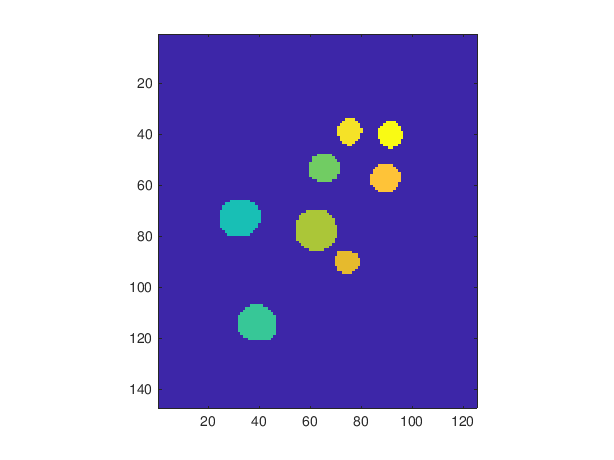

imagesc(mat2gray(max(track(:,:,:,30), [], 3)))
daspect([1,1,1])

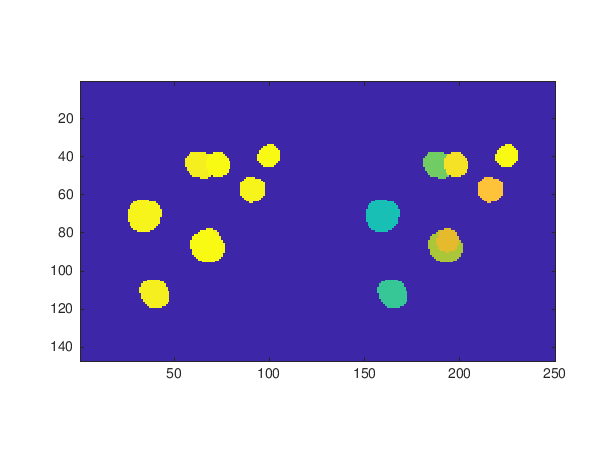

% % Repeat showing Z projection time by time
figure
set(gcf,'Visible','on')
for i = 1:size(track, 4)
    combinedImg = [mat2gray(max(nuc(:,:,:,i), [], 3)), mat2gray(max(track(:,:,:,i), [], 3))];
    imagesc(combinedImg)
    daspect([1,1,1])
    pause(0.3)% Pause ~ second
end

%% ---------------------- Analysis ----------------------

% Calculate features
CC = regionprops(nuc, img, 'Area', 'MeanIntensity');% Not the track
% Volume
vol = cat(1, CC.Area);
vol = vol * 0.44 * 0.44 * 0.5;% resolutions for xyz
% intensity
int = cat(1, CC.MeanIntensity);
% Update data
data = [data, vol, int];% data = x,y,z,t,id,volume,intensity

% Calculate solidity
[r,c,z,t] = size(nuc);
nuc3 = reshape(nuc, [r,c,z*t]);
sol = regionprops3(nuc3, 'Solidity');% Not the track
% Solidity
sol = cat(1, sol.Solidity);
% Update data
data = [data, sol];% data = x,y,z,t,id,volume,intensity

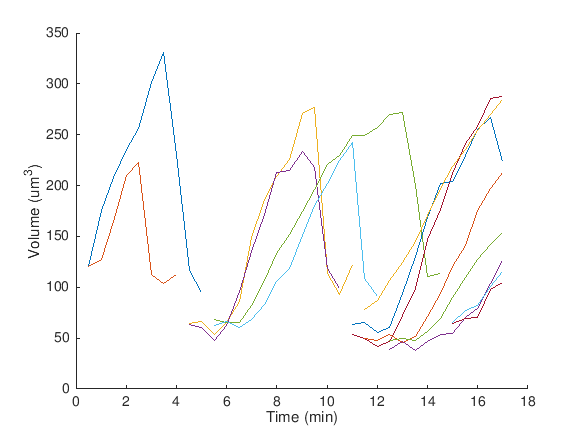

% Plot volume
uniqueIDs = unique(data(:,5));
figure;
hold on
for i=uniqueIDs'
    time = data(data(:,5)==i, 4)*0.5;
    vol = data(data(:,5)==i, 6);
    plot(time, vol);
end
hold off;
xlabel('Time (min)')
ylabel('Volume (um^3)')

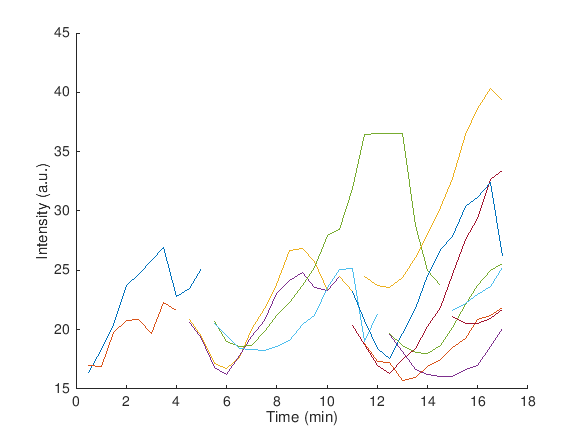

% Plot intensity
uniqueIDs = unique(data(:,5));
figure;
hold on
for i=uniqueIDs'
    time = data(data(:,5)==i, 4)*0.5;
    int = data(data(:,5)==i, 7);
    plot(time, int);
end
hold off;
xlabel('Time (min)')
ylabel('Intensity (a.u.)')

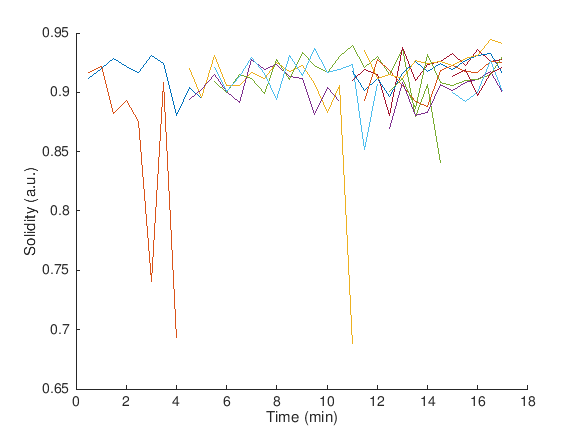

% Plot solidity
uniqueIDs = unique(data(:,5));
figure;
hold on
for i=uniqueIDs'
    time = data(data(:,5)==i, 4)*0.5;
    sol = data(data(:,5)==i, 8);
    plot(time, sol);
end
hold off;
xlabel('Time (min)')
ylabel('Solidity (a.u.)')

%% ---------------------- Visualization ----------------------
% Visualize trajectories of the nuclei in 2D
[r,c,z,t] = size(img);
projectionImg = mean(img, 3); % average value of Z
drawLen = 3;% Length of trajectories
tempImg = zeros(r,c,1,t);
for j = 2:time(end)
    % ids in time j
    idListCurrent = unique(data(data(:,4)==j, 5));
    idListPre = unique(data(data(:,4)==j-1, 5));
    idList = intersect(idListCurrent, idListPre);
    
    for i = idList'%transpose
        % Coordinates of both sides of trajectory lines
        X0 = data(data(:,5)==i & (data(:,4)==j-1), 2);
        X1 = data(data(:,5)==i & (data(:,4)==j), 2);
        Y0 = data(data(:,5)==i & (data(:,4)==j-1), 1);
        Y1 = data(data(:,5)==i & (data(:,4)==j), 1);
        % pixels on the trajectories are computed
        for n = 0:(1/round(sqrt((X1-X0)^2 + (Y1-Y0)^2))):1
            xn = round(X0 +(X1 - X0)*n);
            yn = round(Y0 +(Y1 - Y0)*n);
            tempImg(xn,yn,:,j) = i;
        end
    end
    % Trajectories with nuclei that do not exist at time J are deleted
    tempImg(~ismember(tempImg, idList)) = 0;
    % Draw trajectories within 'drawLen' time points
    trajectoryImg = max(tempImg(:,:,:,max(1, j-drawLen-1):j), [], 4);
    % trajectoryImg is added to the projectionImg, the colors are adjusted
    projectionImg(:,:,:,j) = immultiply(projectionImg(:,:,:,j), ~trajectoryImg);
    trajectoryImg(trajectoryImg>0) = trajectoryImg(trajectoryImg>0) * 7 + 30;
    projectionImg(:,:,:,j) = projectionImg(:,:,:,j) + trajectoryImg;
end

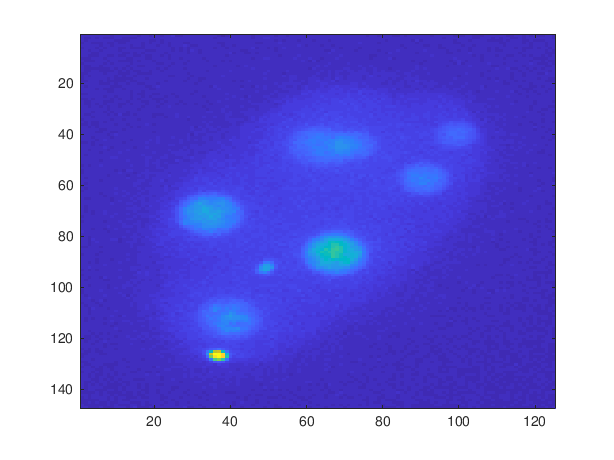

% % Repeat showing Z projection time by time
figure
set(gcf,'Visible','on')
for i = 1:size(track, 4)
    imagesc(projectionImg(:,:,:,i))
    pause(0.3)% Pause ~ second
end